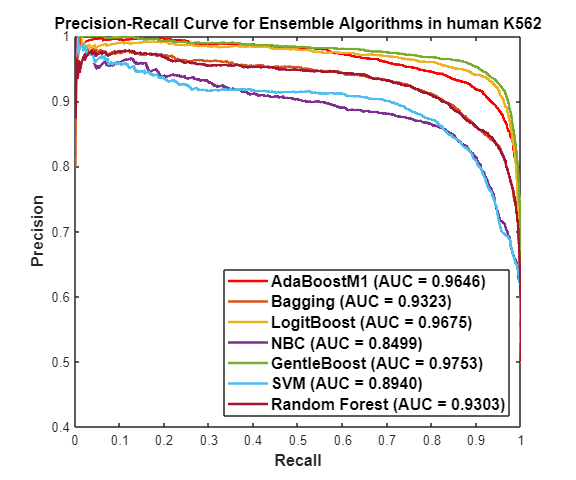


%trainingWindowIntdisStForR
%hs
%K562
%str_png =["hsLung","hsCortex","hsSpleen","hsThyhs"]
%color:'red"、'blue'、green"、'black','cyan'、%%"magenta玫红'、'yellow'、"black'、'white
%legendText{2}
%human




anycell = "K562"; % 只更改细胞名称
openfile = sprintf("trainingWindowIntdisStForR_hs%s.bed", anycell);
fileID = fopen(openfile);
TrainwindowdatadisKc167 = textscan(fileID, '%s %f %f %f %f %f %f %f');
trainingdischiapetKc167 = [TrainwindowdatadisKc167{2:8}];

predictorNames = {'EGC', 'GS', 'DIS', 'EWS', 'GWS', 'EEC'};
inputTable = array2table(trainingdischiapetKc167, 'VariableNames', {'EGC', 'GS', 'DIS', 'EWS', 'GWS', 'EEC', 'column_7'});
predictors = inputTable(:, predictorNames);
response = inputTable.column_7;

% 训练 AdaBoostM1 模型
templateAdaBoost = templateTree('MaxNumSplits', 30);
classificationEnsembleAdaBoost = fitcensemble(predictors, response, 'Method', 'AdaBoostM1', 'NumLearningCycles', 30, 'Learners', templateAdaBoost, 'LearnRate', 0.8, 'ClassNames', [1; 2]);
[validationPredictionsAdaBoost, validationScoresAdaBoost] = kfoldPredict(crossval(classificationEnsembleAdaBoost, 'KFold', 10));

% 训练 Bagging 模型
templateBag = templateTree('MaxNumSplits', 30);
classificationEnsembleBag = fitcensemble(predictors, response, 'Method', 'Bag', 'NumLearningCycles', 30, 'Learners', templateBag, 'ClassNames', [1; 2]);
[validationPredictionsBag, validationScoresBag] = kfoldPredict(crossval(classificationEnsembleBag, 'KFold', 10));

% 训练 LogitBoost 模型
templateLogitBoost = templateTree('MaxNumSplits', 30);
classificationEnsembleLogitBoost = fitcensemble(predictors, response, 'Method', 'LogitBoost', 'NumLearningCycles', 30, 'Learners', templateLogitBoost, 'ClassNames', [1; 2]);
[validationPredictionsLogitBoost, validationScoresLogitBoost] = kfoldPredict(crossval(classificationEnsembleLogitBoost, 'KFold', 10));

% 训练 NBC 模型
classificationNBC = fitcnb(predictors, response, 'ClassNames', [1; 2]);
[~, validationScoresNBC] = predict(classificationNBC, predictors);

% 训练 GentleBoost 模型
templateGentleBoost = templateTree('MaxNumSplits', 30);
classificationEnsembleGentleBoost = fitcensemble(predictors, response, 'Method', 'GentleBoost', 'NumLearningCycles', 30, 'Learners', templateGentleBoost, 'LearnRate', 0.8, 'ClassNames', [1; 2]);
[validationPredictionsGentleBoost, validationScoresGentleBoost] = kfoldPredict(crossval(classificationEnsembleGentleBoost, 'KFold', 10));

% 训练 SVM 模型
classificationSVM = fitcsvm(predictors, response, 'Standardize', true, 'KernelFunction', 'linear');
[~, validationScoresSVM] = kfoldPredict(crossval(classificationSVM, 'KFold', 10));

% 训练 KNN 模型
% classificationKNN = fitcknn(predictors, response);
% [~, validationScoresKNN] = predict(classificationKNN, predictors);

% 训练随机森林模型
templateRF = templateTree('MaxNumSplits', 30);
classificationEnsembleRF = fitcensemble(predictors, response, 'Method', 'Bag', 'NumLearningCycles', 30, 'Learners', templateRF, 'ClassNames', [1; 2]);
[validationPredictionsRF, validationScoresRF] = kfoldPredict(crossval(classificationEnsembleRF, 'KFold', 10));

% 计算并绘制 PR 曲线
figure;
hold on;

% 绘制 AdaBoostM1 的 PR 曲线
[XadaBoost, YadaBoost, TadaBoost, AUCadaBoost] = perfcurve(trainingdischiapetKc167(:, 7), validationScoresAdaBoost(:, 1), 1, 'XCrit', 'reca', 'YCrit', 'prec');
plot(XadaBoost, YadaBoost, 'LineWidth', 1.9, 'DisplayName', 'AdaBoostM1', 'Color', [1, 0, 0]);

% 绘制 Bagging 的 PR 曲线
[Xbag, Ybag, Tbag, AUCbag] = perfcurve(trainingdischiapetKc167(:, 7), validationScoresBag(:, 1), 1, 'XCrit', 'reca', 'YCrit', 'prec');
plot(Xbag, Ybag, 'LineWidth', 1.9, 'DisplayName', 'Bagging');

% 绘制 LogitBoost 的 PR 曲线
[XlogitBoost, YlogitBoost, TlogitBoost, AUClogitBoost] = perfcurve(trainingdischiapetKc167(:, 7), validationScoresLogitBoost(:, 1), 1, 'XCrit', 'reca', 'YCrit', 'prec');
plot(XlogitBoost, YlogitBoost, 'LineWidth', 1.9, 'DisplayName', 'LogitBoost');

% 绘制 NBC 的 PR 曲线
[XNBC, YNBC, TNBC, AUCNBC] = perfcurve(trainingdischiapetKc167(:, 7), validationScoresNBC(:, 1), 1, 'XCrit', 'reca', 'YCrit', 'prec');
plot(XNBC, YNBC, 'LineWidth', 1.9, 'DisplayName', 'NBC');

% 绘制 GentleBoost 的 PR 曲线
[XgentleBoost, YgentleBoost, TgentleBoost, AUCgentleBoost] = perfcurve(trainingdischiapetKc167(:, 7), validationScoresGentleBoost(:, 1), 1, 'XCrit', 'reca', 'YCrit', 'prec');
plot(XgentleBoost, YgentleBoost, 'LineWidth', 1.9, 'DisplayName', 'GentleBoost');

% 绘制 SVM 的 PR 曲线
[Xsvm, Ysvm, Tsvm, AUCsvm] = perfcurve(trainingdischiapetKc167(:, 7), validationScoresSVM(:, 1), 1, 'XCrit', 'reca', 'YCrit', 'prec');
plot(Xsvm, Ysvm, 'LineWidth', 1.9, 'DisplayName', 'SVM');

% 绘制 KNN 的 PR 曲线
% [Xknn, Yknn, Tknn, AUCknn] = perfcurve(trainingdischiapetKc167(:, 7), validationScoresKNN(:, 1), 1, 'XCrit', 'reca', 'YCrit', 'prec');
% plot(Xknn, Yknn, 'LineWidth', 1.9, 'DisplayName', 'KNN');

% 绘制随机森林的 PR 曲线
[XRF, YRF, TRF, AUCrf] = perfcurve(trainingdischiapetKc167(:, 7), validationScoresRF(:, 1), 1, 'XCrit', 'reca', 'YCrit', 'prec');
plot(XRF, YRF, 'LineWidth', 1.9, 'DisplayName', 'Random Forest');

% 计算 AUC 值
AUCadaBoost = round(AUCadaBoost, 4);
AUCbag = round(AUCbag, 4);
AUClogitBoost = round(AUClogitBoost, 4);
AUCNBC = round(AUCNBC, 4);
AUCgentleBoost = round(AUCgentleBoost, 4);
AUCsvm = round(AUCsvm, 4);
% AUCknn = round(AUCknn, 4);
AUCrf = round(AUCrf, 4);

% 创建图例文本
legendText = {
    sprintf('AdaBoostM1 (AUC = %.4f)', AUCadaBoost),
    sprintf('Bagging (AUC = %.4f)', AUCbag),
    sprintf('LogitBoost (AUC = %.4f)', AUClogitBoost),
    sprintf('NBC (AUC = %.4f)', AUCNBC),
    sprintf('GentleBoost (AUC = %.4f)', AUCgentleBoost),
    sprintf('SVM (AUC = %.4f)', AUCsvm),
    % sprintf('KNN (AUC = %.4f)', AUCknn),
    sprintf('Random Forest (AUC = %.4f)', AUCrf)
};

% 设置图例和标签
xlabel('Recall', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Precision', 'FontSize', 12, 'FontWeight', 'bold');
title('Precision-Recall Curve for Ensemble Algorithms in human K562', 'FontSize', 12, 'FontWeight', 'bold');

% 设置图例在右下角
legend(legendText, 'Location', 'southeast', 'TextColor', 'black', 'FontSize', 12, 'FontWeight', 'bold');
box on; % 添加边框到整个图形

% 设置坐标轴为正方形
width = 6; % 设置宽度为6英寸
height = width / 1.2; % 计算高度
set(gcf, 'Units', 'Inches', 'Position', [1 1 width height]);

hold off;

% 保存图像为 PNG 文件
pngString = sprintf("Comparison_PR_curve_with_AUChuman.png");
print(gcf, pngString, '-dpng', '-r600');